## MT3005 - Clase 7

De nuevo estaremos considerando el ejemplo del manipulador serial RR

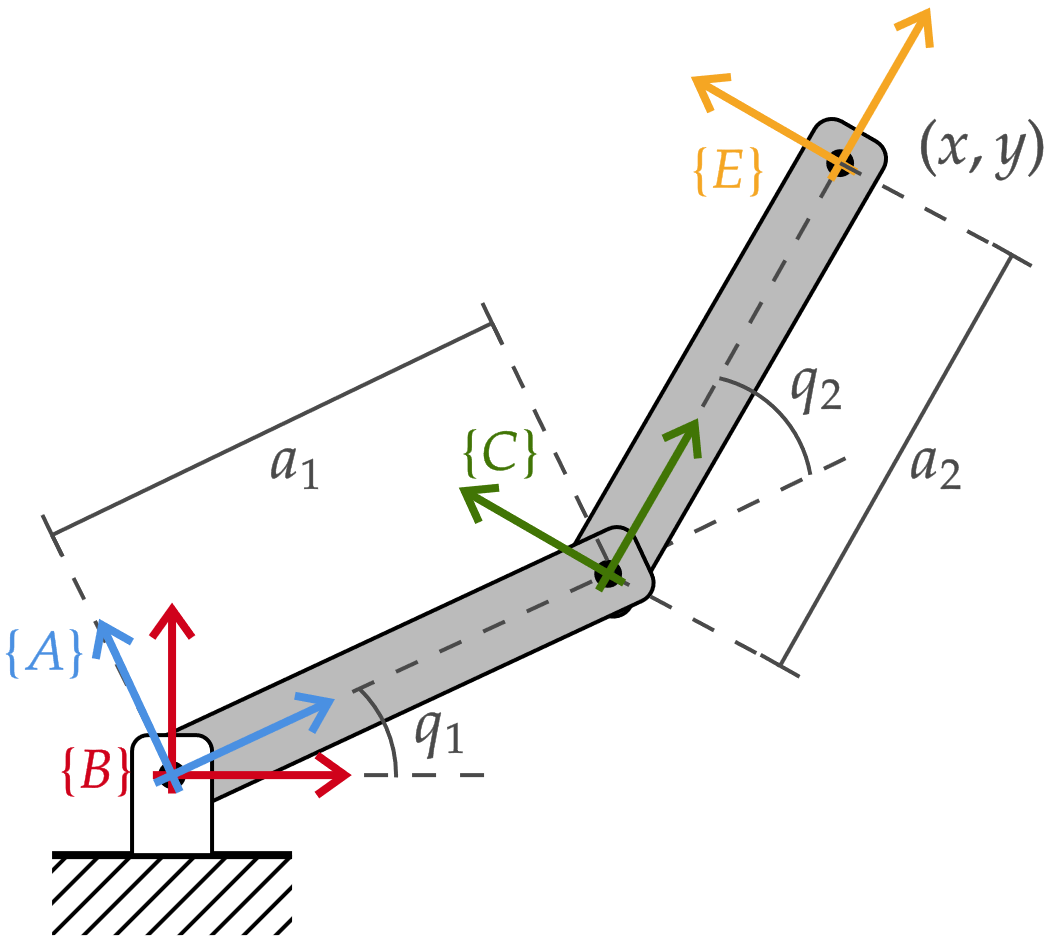

para el cual calcularemos la cinemática diferencial y el elipsoide de velocidad lineal, tanto "a mano" como empleando las herramientas de la Robotics Toolbox. Iniciamos encontrando el jacobiano de posición mediante la cinemática directa:

% Parámetros del robot
a1 = 1;
a2 = 1;
syms q1 q2 vx vy

% Definimos la cinemática directa del manipulador
BT_E = simplify(trot2(q1)*transl2(a1,0)*trot2(q2)*transl2(a2,0));

% Extraemos la posición del efector final en función a la configuración
p(q1, q2) = BT_E(1:2,3);

% Determinamos el jacobiano de posición
Jv(q1, q2) = jacobian(p(q1, q2), [q1, q2])

$$Jv(q1, q2) = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

Ya con el jacobiano procedemos a graficar el manipulador en una configuración de prueba junto con los ejes del elipsoide de velocidad lineal:

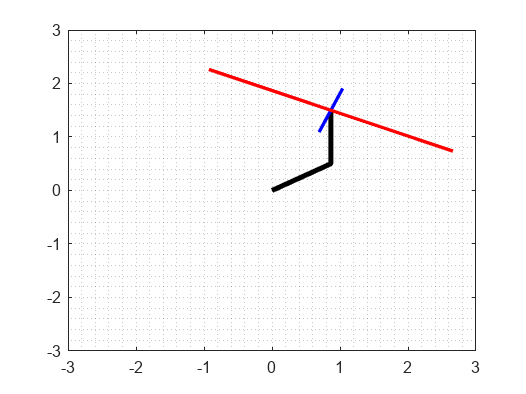

% Configiuración de prueba
cfg = [pi/6, pi/3]; 

% Elipse empleando la matriz A
A = double( Jv(cfg(1),cfg(2)) * Jv(cfg(1),cfg(2)).' );
[V, D] = eig(A); % eigenvalores y eigenvectores
figure;
efp = double(p(cfg(1), cfg(2))); % posición del efector final
plot([0, a1*cos(cfg(1)), efp(1)], [0, a1*sin(cfg(1)), efp(2)], 'k', ...
    'LineWidth', 3);
grid minor;
hold on;

% Ejes del elipse
ax = sqrt(D(1,1))*V(1,1);
ay = sqrt(D(1,1))*V(2,1);
bx = sqrt(D(2,2))*V(1,2);
by = sqrt(D(2,2))*V(2,2);
plot([efp(1)+ ax, efp(1)-ax], [efp(2)+ ay, efp(2)-ay], 'b', 'LineWidth', 2);
plot([efp(1)+ bx, efp(1)-bx], [efp(2)+ by, efp(2)-by], 'r', 'LineWidth', 2);
xlim([-3,3]); ylim([-3,3]);
hold off;

Para el caso de la Robotics Toolbox, basta con definir de nuevo el robot mediante un objeto SerialLink y luego especificar que se quiere visualizar el elipsoide de velocidad durante la llamada a la función teach:

% Definimos al manipulador planar RR
J1 = Revolute('a',a1);
J2 = Revolute('a',a2);
pRR = SerialLink([J1, J2], 'name', 'planRR')

 
pRR = 
 
planRR:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


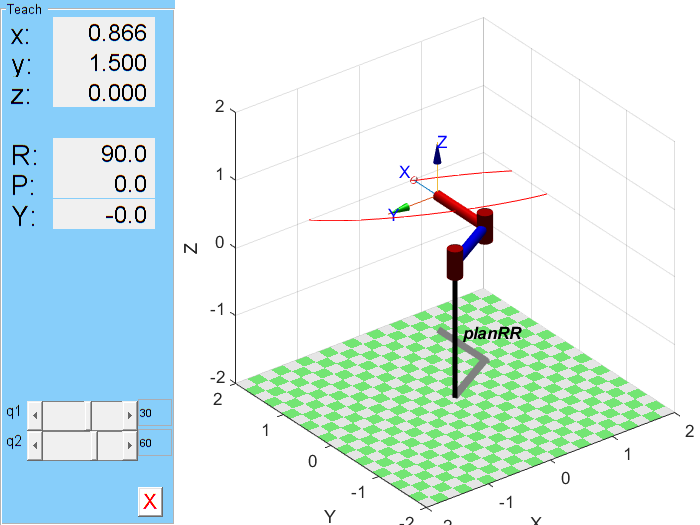


% Se visualiza el manipulador con el elipsoide
figure;
pRR.plot(cfg1);
pRR.teach('callback', @(r,q) r.vellipse(q), 'view', 'top');

Nótese que puede visualizarse el elipsoide de fuerza (lineal) cambiando de vellipse a fellipse.

Podemos visualizar un caso más interesante en 3D como el del robot Puma560:

% Se carga el modelo del robot
mdl_puma560;

% Se establece una configuración de prueba
cfg = 10*ones(1,6)*pi/180;

% Se visualiza el manipulador junto con su elipsoide de fuerza
p560.plot3d(cfg);

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


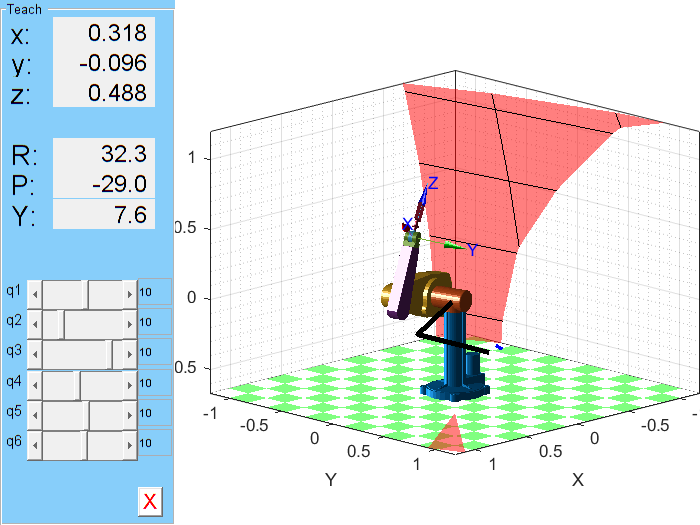

p560.teach('callback', @(r,q) r.fellipse(q), 'view', 'top');